# Hierarchical HGF (h2gf) Demo

close all; clear variables; clc;
addpath(genpath('..'));

## Preparation of the model

You should be familiar with the HGF Toolbox (part of TAPAS) in order to understand what follows. If you're not, a good way to get started with it is to work through its interactive demo in HGF/hgf_demo.mlx.

Once you have a basic understanding of how to use the HGF Toolbox, you can start with the h2gf is by initializing a structure to hold the HGF model definition.

hgf = struct('c_prc', [], 'c_obs', []);

Next, we need to choose a perceptual model and the corresponding reparameteriztion function.

hgf.c_prc.prc_fun = @tapas_hgf_binary;
hgf.c_prc.transp_prc_fun = @tapas_hgf_binary_transp;

Then we do the same for the observation model.

hgf.c_obs.obs_fun = @tapas_unitsq_sgm; 
hgf.c_obs.transp_obs_fun = @tapas_unitsq_sgm_transp; 

Now we run the config function of the perceptual model and copy the priors and number of levels of the perceptual model into the hgf structure.

config = tapas_hgf_binary_config();
hgf.c_prc.priormus = config.priormus;
hgf.c_prc.priorsas = config.priorsas;
hgf.c_prc.n_levels = config.n_levels;
clear config

We set the priors of the observational model directly.

hgf.c_obs.priormus = 0.5;
hgf.c_obs.priorsas = 1;

All of the above is familiar from non-hierarchical applications of the HGF to a single dataset as implemented in the HGF Toolbox. However, once we move to the hierarchical estimation of parameters across several datasets, it is useful to assign each prior a weight in terms of additional, virtual datasets. This is parameterized by $\eta$ (eta), which weights the priors with respect to the observed datasets. Its value corresponds to the number of virtual datasets represented by the priors. For example, if we have data from ten real subjects and set $\eta$ to ten, the priors will have a weight equal to that of the data. By default $\eta$ is one, corresponding to one virtual dataset.

$\eta$ can be a scalar, setting the same weight across all priors; or a vector, setting a particular weight for each parameter's prior. If eta is a vector, its length needs to be the sum of the lengths hgf.c_prc.priormus and hgf.c_obs.priormus.

hgf.empirical_priors = struct('eta', []);
hgf.empirical_priors.eta = 1;

## Data simulation

We choose a range of values for the parameters $\omega_2$ (evolution rate at the second level) and $\omega_3$ (evolution rate at the third level). The rest of the parameters are held constant.

om2_values = [-5, -3.5, -2];
om3_values = [-8, -5, -2];

[om2, om3] = meshgrid(om2_values, om3_values);
om2 = om2(:)';
om3 = om3(:)';
gridsize = length(om2);

We choose a range of response noise levels (i.e., values of the parameter $\zeta$). Higher values of $\zeta$ mean *less* noise.

ze = [1, 4, 8];
numnoiselevels = length(ze);

Finally, we choose a number of simulations per grid point.

numsim = 8;

 Then we initialize structure arrays for the simulations and for the 'data' argument of tapas_h2gf_estimate().

sim = struct('u', cell(gridsize, numnoiselevels, numsim),...
             'ign', [],...
             'c_sim', [],...
             'p_prc', [],...
             'c_prc', [],...
             'traj', [],...
             'p_obs', [],...
             'c_obs', [],...
             'y', []);


data = struct('y', cell(gridsize, numnoiselevels, numsim),...
              'u', [],...
              'ign', [],...
              'irr', []);

We load the example inputs $u$ and generate simulated data with the chosen range of parameter settings

[~, u] = tapas_h2gf_load_example_data();

for i = 1:gridsize
    for j = 1:numnoiselevels
        for k = 1:numsim
            % Simulation
            sim(i,j,k) = tapas_simModel(u,...
                                        'tapas_hgf_binary', [NaN,...
                                                             1,...
                                                             1,...
                                                             NaN,...
                                                             1,...
                                                             1,...
                                                             NaN,...
                                                             0,...
                                                             0,...
                                                             1,...
                                                             1,...
                                                             NaN,...
                                                             om2(i),...
                                                             om3(i)],...
                                        'tapas_unitsq_sgm', ze(j),...
                                        i*j*k);
            % Simulated responses
            data(i,j,k).y = sim(i,j,k).y;
            % Inputs
            data(i,j,k).u = sim(i,j,k).u;
        end
    end
end

Ignored trials: none
Ignored trials: none
Ignored trials: none
Ignored trials: none
Ignored trials: none
Ignored trials: none
Ignored trials: none
Ignored trials: none
Ignored trials: none
Ignored trials: none
Ignored trials: none
Ignored trials: none
Ignored trials: none
Ignored trials: none
Ignored trials: none
Ignored trials: none
Ignored trials: none
Ignored trials: none
Ignored trials: none
Ignored trials: none
Ignored trials: none
Ignored trials: none
Ignored trials: none
Ignored trials: none
Ignored trials: none
Ignored trials: none
Ignored trials: none
Ignored trials: none
Ignored trials: none
Ignored trials: none
Ignored trials: none
Ignored trials: none
Ignored trials: none
Ignored trials: none
Ignored trials: none
Ignored trials: none
Ignored trials: none
Ignored trials: none
Ignored trials: none
Ignored trials: none
Ignored trials: none
Ignored trials: none
Ignored trials: none
Ignored trials: none
Ignored trials: none
Ignored trials: none
Ignored trials: none
Ignored trial

clear i j k

## Sampler configuration

The h2gf uses sampling for inference on parameter values. To configure the sampler, we first need to initialize the structure holding the parameters of the inference.

pars = struct();

We set some parameters explicitly:

Number of samples stored.

pars.niter = 500;

Number of samples in the burn-in phase.

pars.nburnin = 500;

Number of chains.

pars.nchains = 8;

Parameters not explicitly defined here take the default values set in tapas_h2gf_inference.m.

## Estimation of a single dataset

Each of our simulated datasets contains data from as many virtual subjects as there are points in our simulation grid (i.e., N = gridsize). We start by estimating the first of our simulated datasets at the lowest noise level (i.e., highest $\zeta$). This corresponds to the workflow when working with actual data.

First, we initialize a structure holding the results of the inference.

inference = struct();

Then we run the estimation.

h2gf_est = tapas_h2gf_estimate(data(:,numnoiselevels,1), hgf, inference, pars);

Sample: 400
Accept rate: 0.41, 0.43, 0.41, 0.39, 0.31, 0.22, 0.13, 0.08, 
Likelihood: -882.28, -1233.89, -1537.90, -916.08, -654.95, -470.31, -420.55, -421.84, 
Sample: 900
Accept rate: 0.43, 0.46, 0.45, 0.42, 0.37, 0.23, 0.17, 0.09, 
Likelihood: -923.49, -947.53, -939.25, -823.40, -583.27, -440.85, -425.90, -415.76, 


We can now look at the belief trajectories of individual subjects. These are the trajectories implied by the median posterior parameter values.

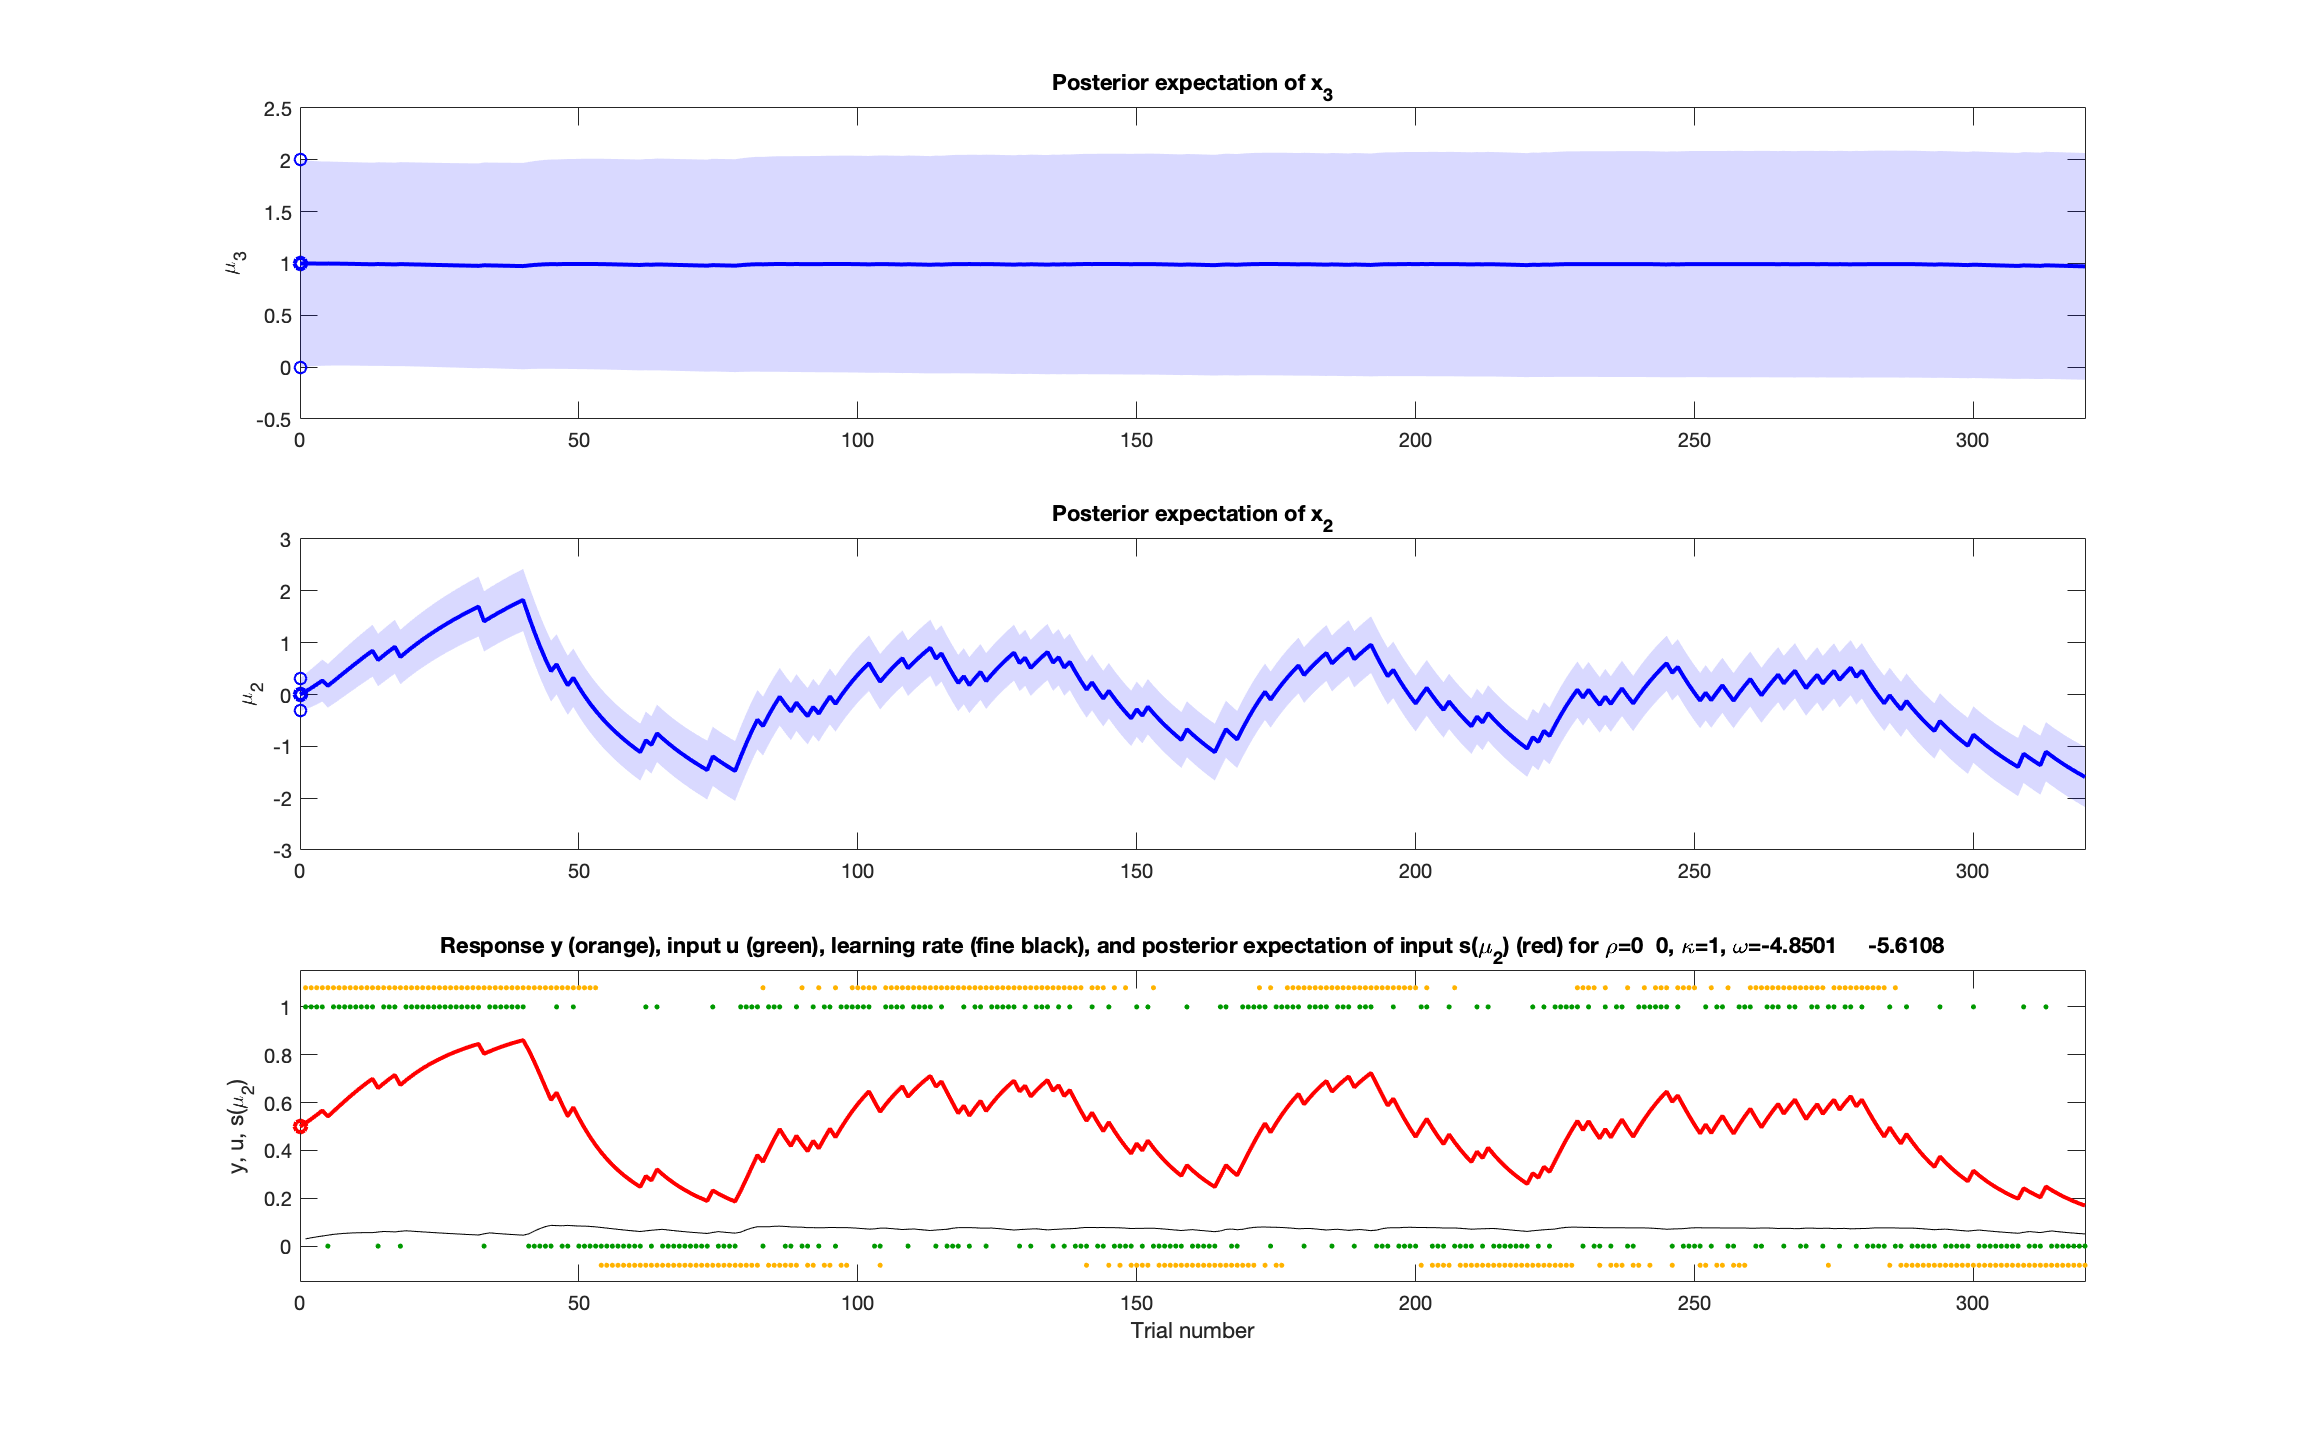

tapas_hgf_binary_plotTraj(h2gf_est.summary(1))

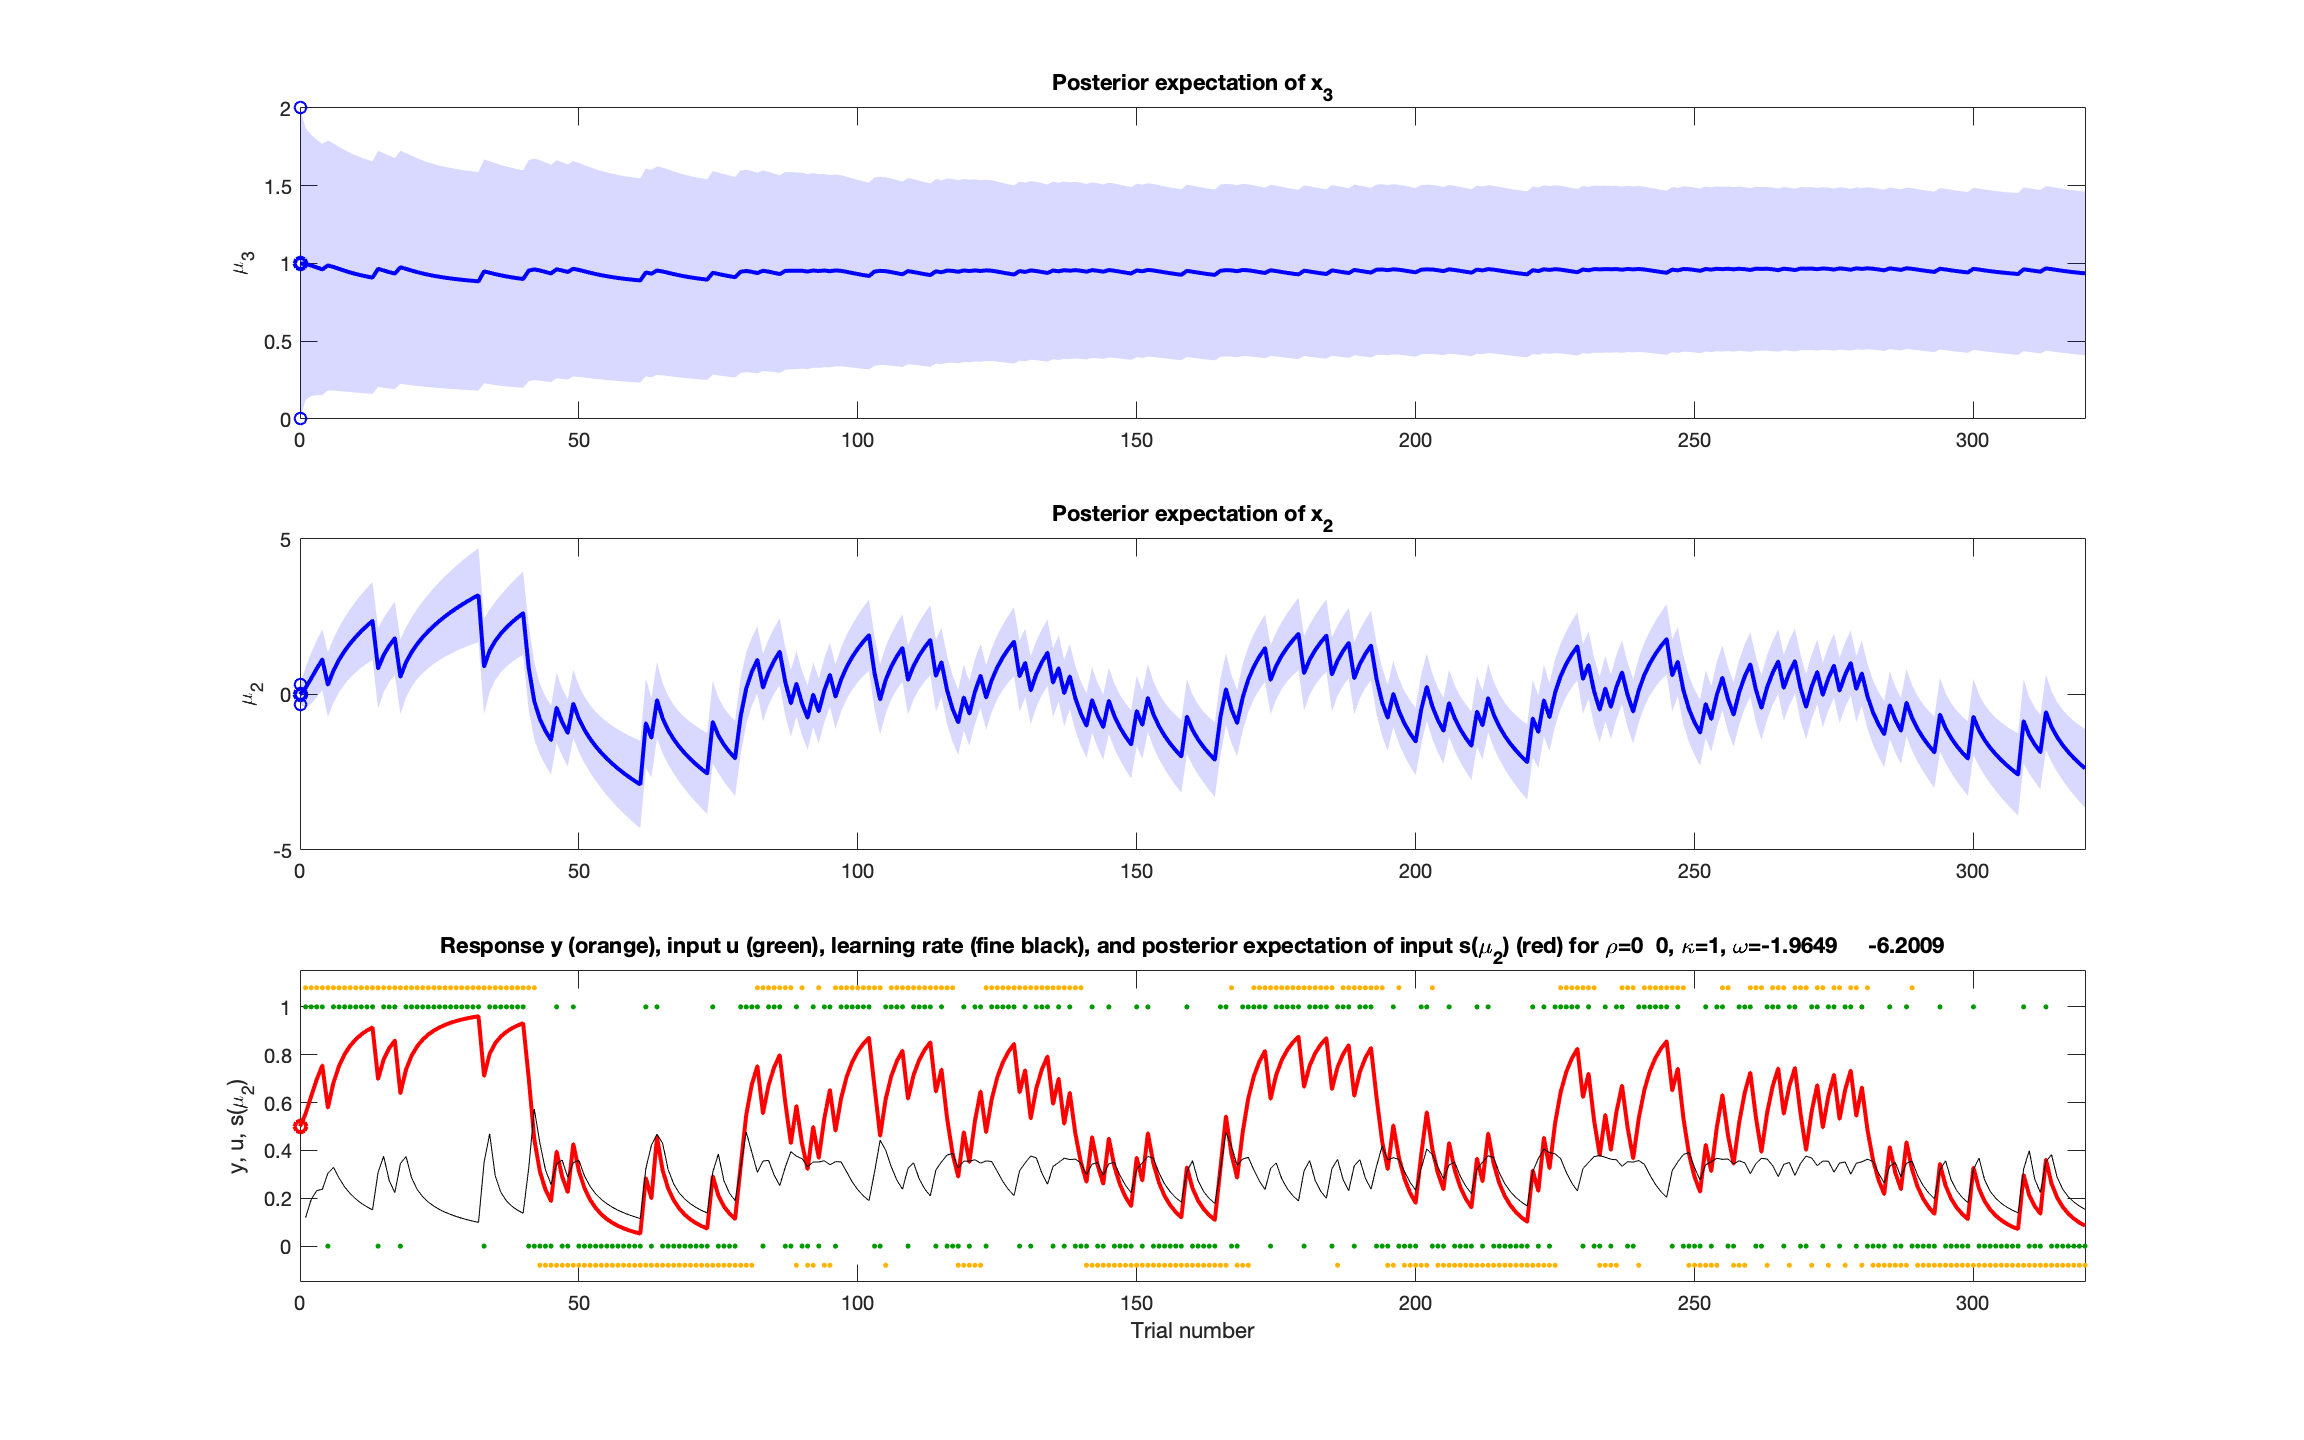

tapas_hgf_binary_plotTraj(h2gf_est.summary(gridsize))

All the plotting and diagnostic functions from the HGF Toolbox work with the 'summary' substructure of the h2gf output.

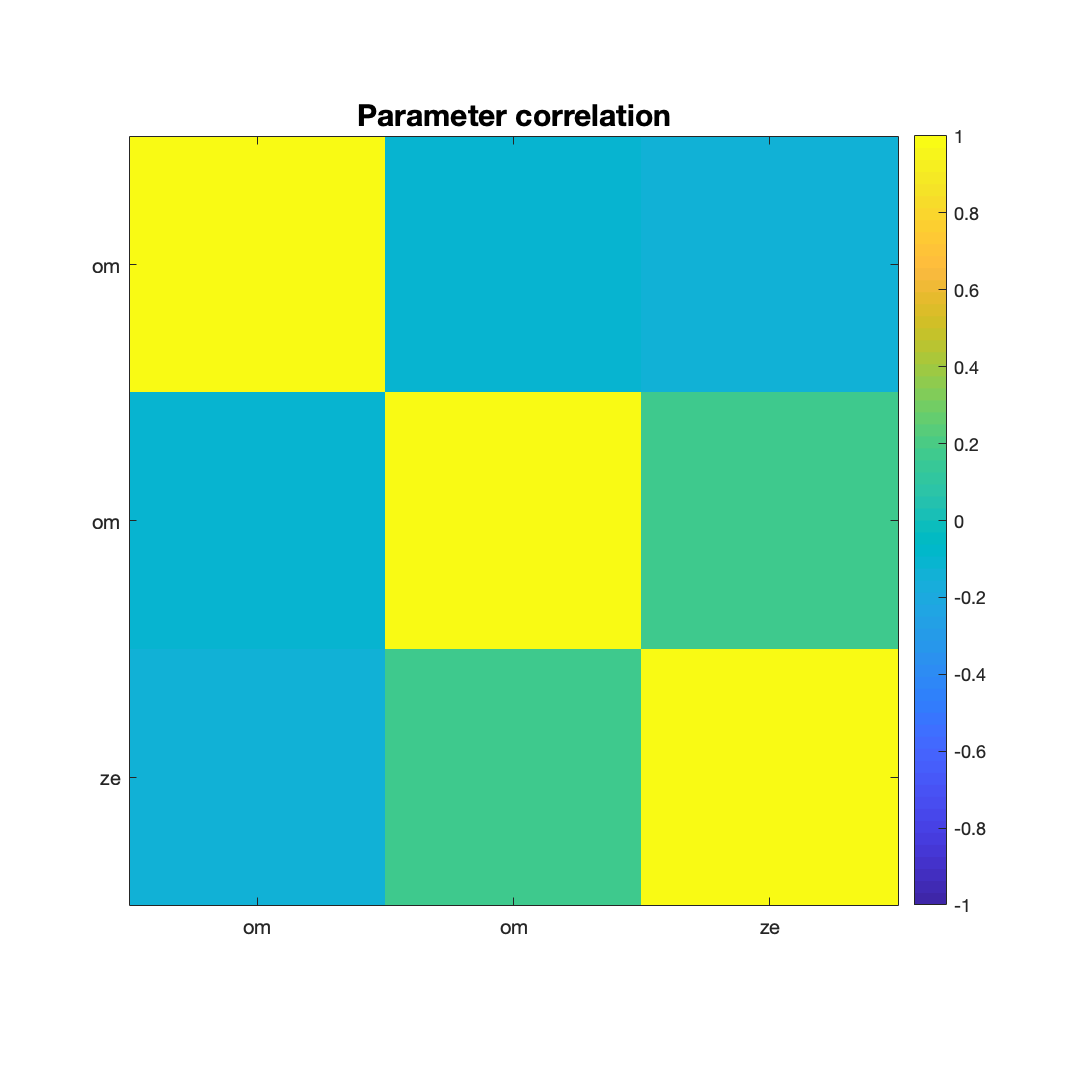

tapas_fit_plotCorr(h2gf_est.summary(1))

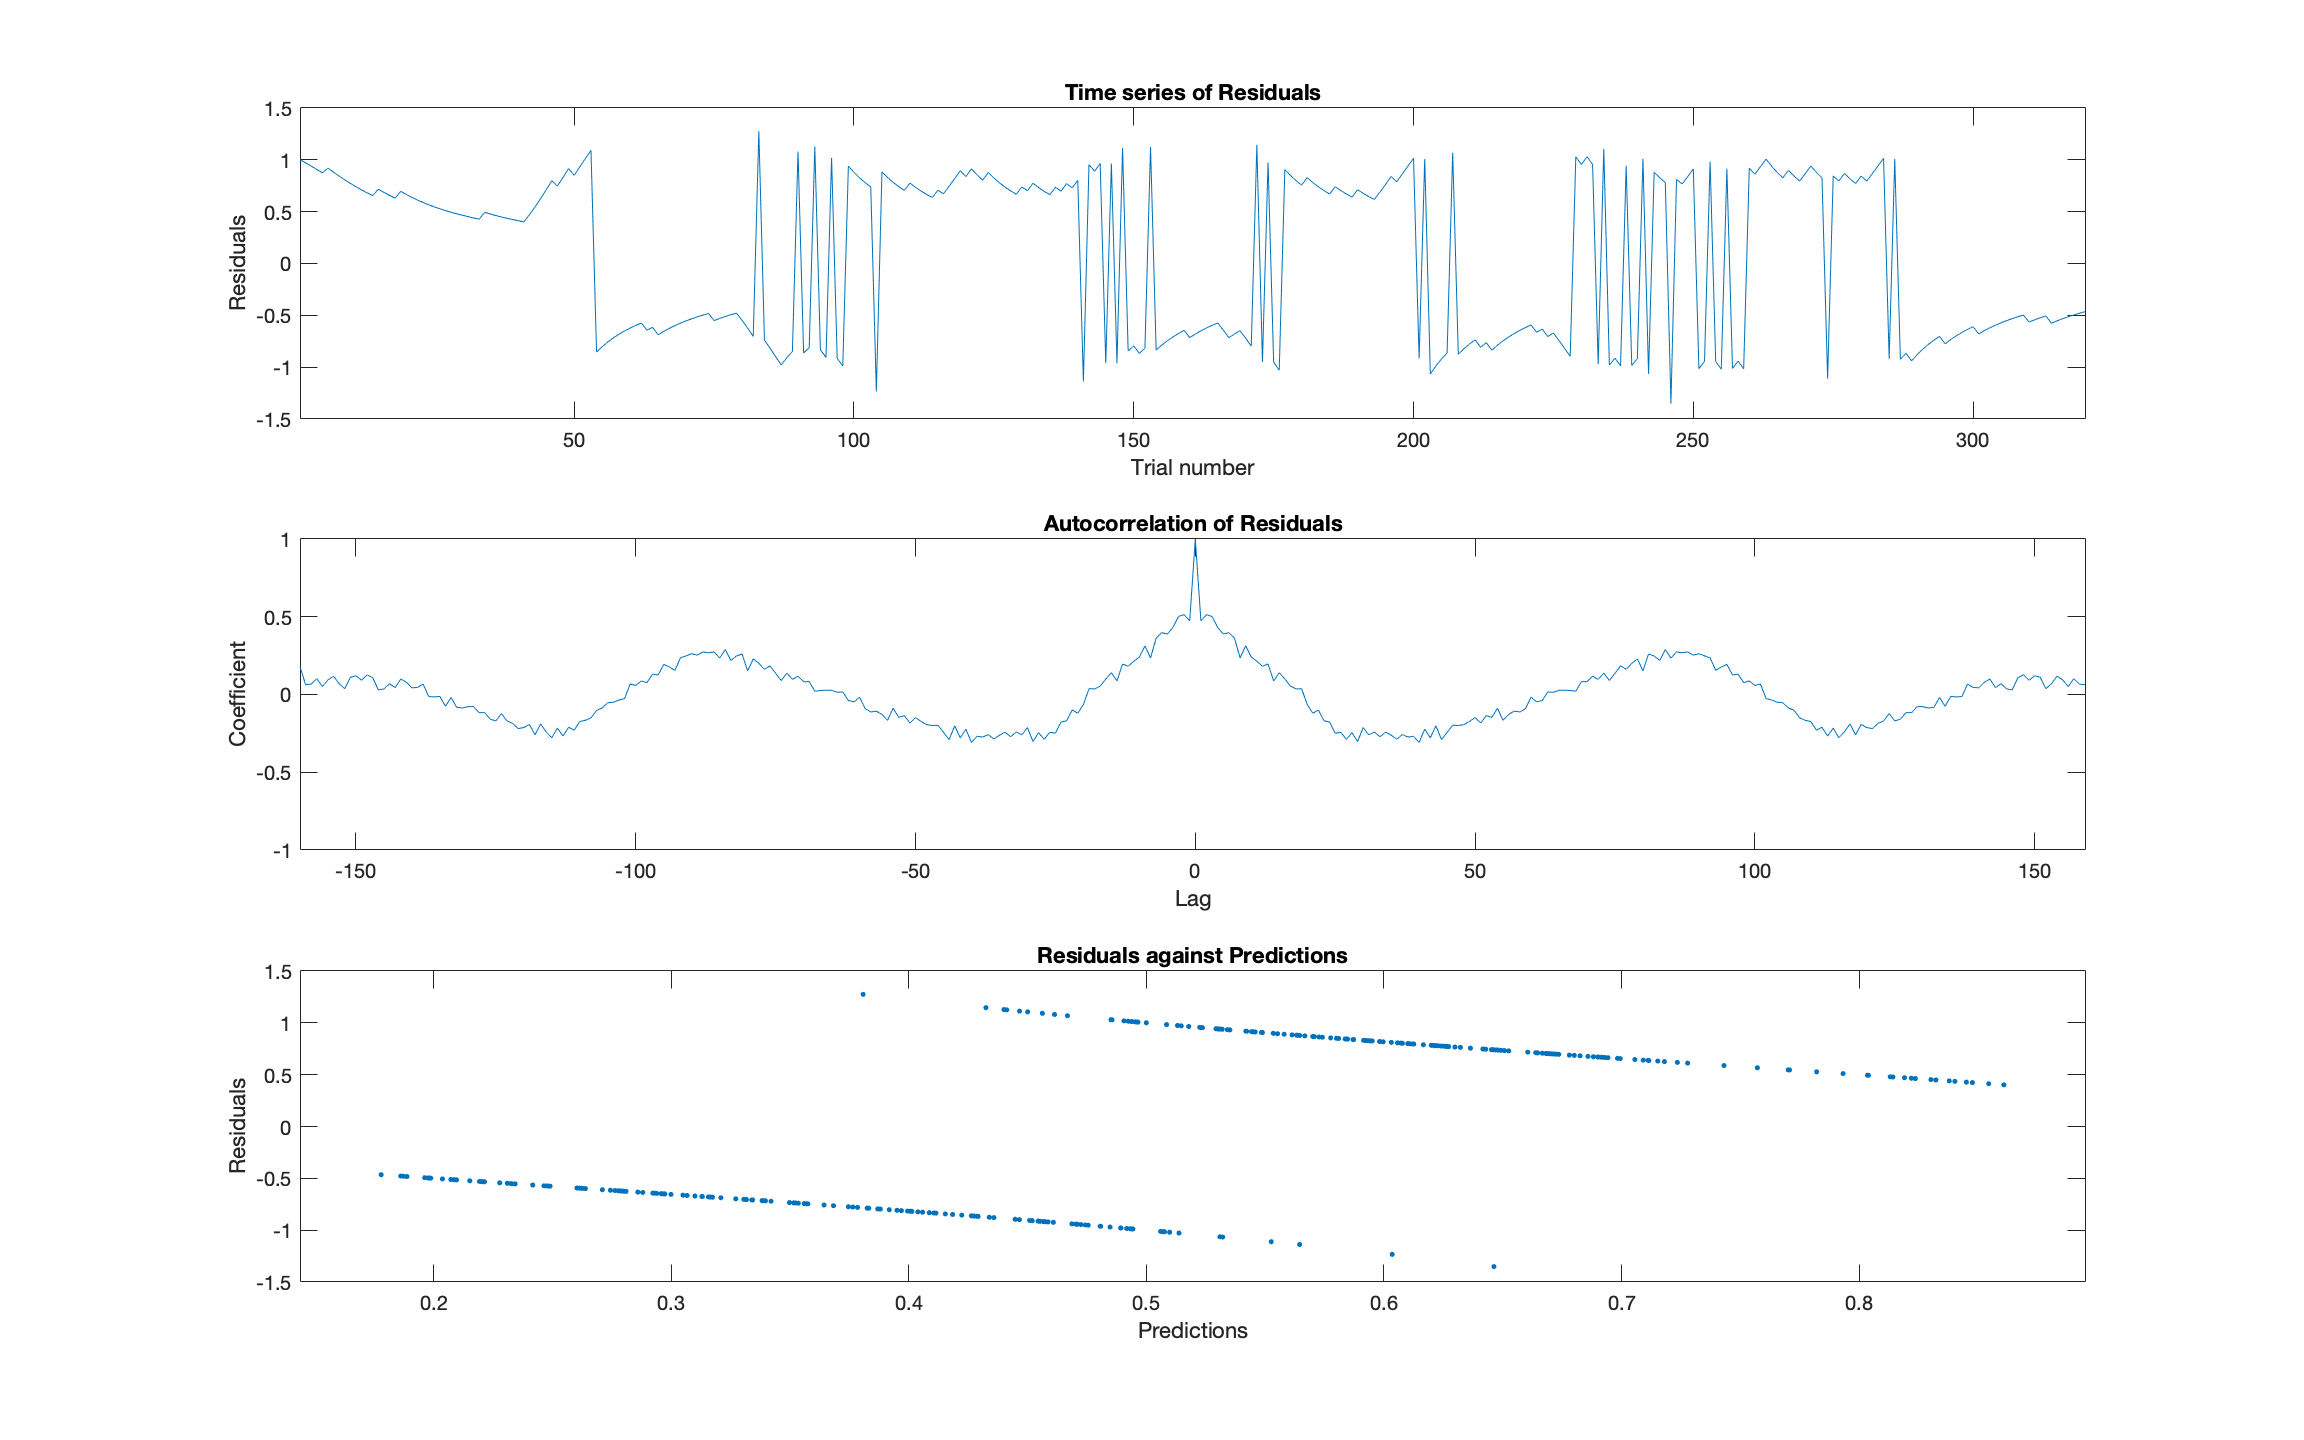

tapas_fit_plotResidualDiagnostics(h2gf_est.summary(1))

## Estimation of all datasets

In order to assess whether the parameters we varied ($\omega_2$ and $\omega_3$) can be recovered, and how recovery is affected by response noise, we need to estimate all datasets at all noise levels. In the interest of time, the estimation is commented out here, and we simply load estimates made previously. To perform your own estimation, uncomment the estimation and comment the loading of the estimates instead.

% est = struct('data', cell(numnoiselevels, numsim),...
%              'model', [],...
%              'inference', [],...
%              'samples_theta', [],...
%              'fe', [],...
%              'llh', [],...
%              'accuracy', [],...
%              'T', [],...
%              'hgf', [],...
%              'summary', []);

% for i = 1:numnoiselevels
%     for j = 1:numsim
%         est(i,j) = tapas_h2gf_estimate(data(:,i,j), hgf, inference, pars);
%     end
% end

Sample: 400
Accept rate: 0.45, 0.41, 0.41, 0.42, 0.35, 0.28, 0.21, 0.13, 
Likelihood: -1837.73, -1850.28, -1962.93, -1710.86, -1686.36, -1678.05, -1651.61, -1639.92, 
Sample: 900
Accept rate: 0.45, 0.45, 0.45, 0.41, 0.43, 0.35, 0.24, 0.16, 
Likelihood: -2077.31, -2271.70, -1992.35, -1756.27, -1697.44, -1670.43, -1653.45, -1639.63, 
Sample: 400
Accept rate: 0.43, 0.40, 0.43, 0.43, 0.36, 0.29, 0.20, 0.13, 
Likelihood: -2407.48, -2492.59, -1753.70, -1735.46, -1727.64, -1697.48, -1685.98, -1676.94, 
Sample: 900
Accept rate: 0.42, 0.45, 0.45, 0.44, 0.42, 0.33, 0.27, 0.16, 
Likelihood: -2595.47, -2015.72, -1762.80, -1704.53, -1733.96, -1709.38, -1687.51, -1677.47, 
Sample: 400
Accept rate: 0.44, 0.47, 0.41, 0.40, 0.35, 0.29, 0.18, 0.16, 
Likelihood: -2016.56, -2162.43, -1936.86, -2002.08, -1761.65, -1752.78, -1723.13, -1709.50, 
Sample: 900
Accept rate: 0.46, 0.46, 0.43, 0.43, 0.40, 0.35, 0.26, 0.22, 
Likelihood: -2466.46, -2152.96, -2250.53, -1780.74, -1798.08, -1723.78, -1713.44, -1705.85,

Sample: 400
Accept rate: 0.43, 0.44, 0.42, 0.41, 0.33, 0.21, 0.13, 0.08, 
Likelihood: -1249.06, -1223.61, -1222.37, -1016.72, -883.95, -811.10, -793.39, -781.84, 
Sample: 900
Accept rate: 0.43, 0.49, 0.44, 0.53, 0.34, 0.24, 0.19, 0.10, 
Likelihood: -1283.62, -1928.84, -1000.35, -1132.13, -902.26, -821.04, -790.20, -783.43, 


Sample: 400
Accept rate: 0.41, 0.44, 0.41, 0.38, 0.31, 0.20, 0.13, 0.09, 
Likelihood: -1106.58, Inf, -1022.99, -992.29, -929.74, -804.29, -786.09, -768.09, 
Sample: 900
Accept rate: 0.43, 0.02, 0.43, 0.41, 0.33, 0.28, 0.16, 0.10, 
Likelihood: -949.40, Inf, -1506.84, -1063.42, -915.57, -838.72, -783.58, -772.35, 
Sample: 400
Accept rate: 0.43, 0.43, 0.43, 0.38, 0.30, 0.21, 0.14, 0.08, 
Likelihood: -1205.69, -1196.08, -1207.56, -1059.15, -914.39, -821.14, -802.88, -776.31, 
Sample: 900
Accept rate: 0.44, 0.43, 0.43, 0.41, 0.34, 0.25, 0.15, 0.10, 
Likelihood: -1126.01, -1198.96, -1080.70, -1072.03, -903.57, -825.10, -791.24, -778.28, 
Sample: 400
Accept rate: 0.43, 0.45, 0.41, 0.39, 0.32, 0.20, 0.12, 0.08, 
Likelihood: -1067.19, -1102.22, -1355.19, -1058.17, -840.71, -799.14, -766.50, -755.13, 
Sample: 900
Accept rate: 0.42, 0.47, 0.41, 0.41, 0.34, 0.27, 0.16, 0.10, 
Likelihood: -1074.42, -1167.14, -1282.60, -1102.78, -925.88, -848.13, -759.43, -746.68, 
Sample: 400
Accept rate: 0.41, 0.4

% clear i j

load('h2gf_demo_est.mat')

We gather the estimates of $\omega_2$ and $\omega_3$ for all grid points, noise levels, and simulated datasets.

om2_est = NaN(gridsize, numnoiselevels, numsim);
om3_est = NaN(gridsize, numnoiselevels, numsim);

for i = 1:gridsize
    for j = 1:numnoiselevels
        for k = 1:numsim
            om2_est(i,j,k) = est(j,k).summary(i).p_prc.om(2);
            om3_est(i,j,k) = est(j,k).summary(i).p_prc.om(3);
        end
    end
end
clear i j k

Plotting the distribution of median samples of $\omega_2$ for all grid points shows that unless noise is very high, this parameter can be recovered.

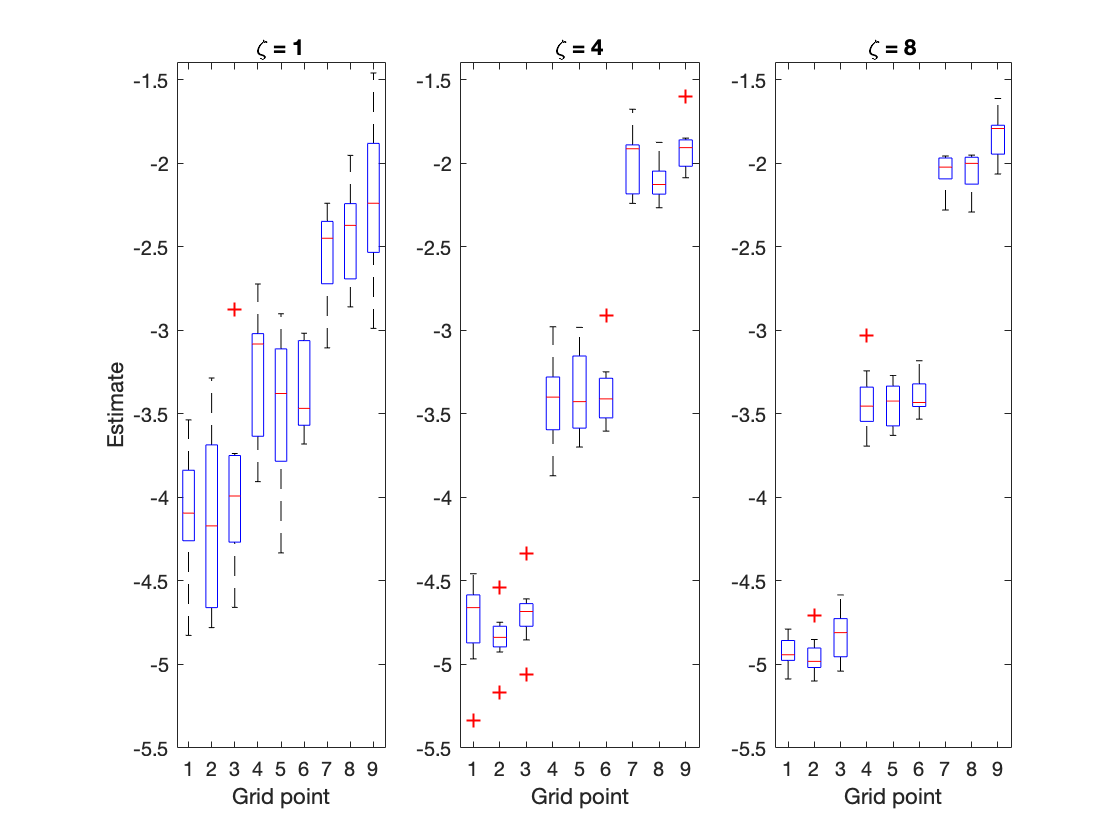

figure;
subplot(1,3,1);
boxplot(squeeze(om2_est(:,1,:))');
ylim([-5.5 -1.4])
title('\zeta = 1')
xlabel('Grid point');
ylabel('Estimate');
subplot(1,3,2);
boxplot(squeeze(om2_est(:,2,:))');
ylim([-5.5 -1.4])
title('\zeta = 4')
xlabel('Grid point');
subplot(1,3,3);
boxplot(squeeze(om2_est(:,3,:))');
ylim([-5.5 -1.4])
title('\zeta = 8')
xlabel('Grid point');

On the other hannd, plotting the distribution of median samples of $\omega_3$ for all grid points shows that this parameter is not recoverable regardless of noise level.

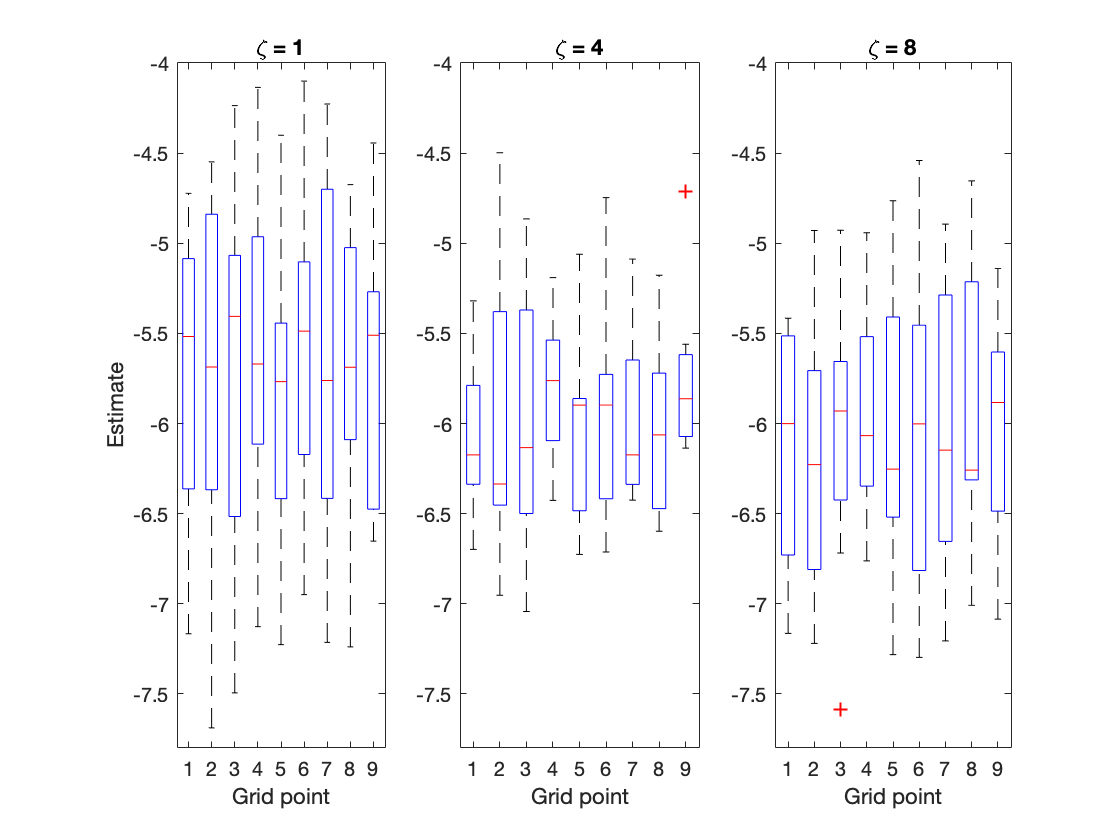

figure;
subplot(1,3,1);
boxplot(squeeze(om3_est(:,1,:))');
ylim([-7.8 -4.0])
title('\zeta = 1')
xlabel('Grid point');
ylabel('Estimate');
subplot(1,3,2);
boxplot(squeeze(om3_est(:,2,:))');
ylim([-7.8 -4.0])
title('\zeta = 4')
xlabel('Grid point');
subplot(1,3,3);
boxplot(squeeze(om3_est(:,3,:))');
ylim([-7.8 -4.0])
title('\zeta = 8')
xlabel('Grid point');

In order to understand how well the model is able to do under our different noise conditions, we calculate the mean log-likelihood for each noise level.

meanllh = zeros(1,numnoiselevels);

for i = 1:numnoiselevels
    for j = 1:numsim
        meanllh(i) = meanllh(i) + mean(est(i,j).llh{1},'all')/numsim;
    end
end
clear i j

meanllh

meanllh =  -212.9239       Inf  -82.3124
